# Project 2

Ross Smyth

FYI if you actually try to run my stuff, the entry point is this file (the .mlx file). This file intializes, runs, and cleans everything up.

clear, clc, close all
addpath data documents scripts Models

## Summary

For this project a control system needed to be designed for a cart system. Given is a plant model of the cart as a transfer function with force input in Newtons and position output.


$$\frac{Y\left(s\right)}{U\left(s\right)}=\frac{25}{s^2 +4s+25}$$


To design this system, first the open-loop step response of the plant was observed for reference. The step response was interesting as the plant will settle to the numerical force value. This means that the controller of the system, once designed, won't have to work very hard as the cart system itself already settles. 

The overall system also has a sensor with a time constant. This time constant can be configuredm, but will start out a 0.1 seconds. The transfer function of the sensor is the following:


$$\frac{Y\left(s\right)}{N\left(s\right)}=\frac{1}{\tau s+1}$$


For the controller design, MATLAB's `ControlSystemDesigner` was used as it shows the response of the system as the gains are changed. A good controller was found with the PID controller and so that is the controller used in the end. A function was then developed that can take in simulation data, and spit out the estimated incentive/cost.

## Controller Design

### PI Controller

First a proportinal controller was insepcted. This controller wasn't the worst, but not great either so a proportional-integral controller was baselined instead. With unity gains for both proportional and integral gains the system responds pretty well for not changing anything, most likely related to the statement above of since the system already emulates a spring pretty well the controller won't have to do much. The gain was increased a little bit to decrease the rise time, but that was all that was done initially. The controller is shown below. Below the controller is the continuous-time step response. This looks fine and dandy, until it is actually ran. 

A note is that the sensor is being fed into a Kalman filter for both controllers listed here. This is because I cannot think of a downside as it should eliminate or reduce the phase-lag from the sensor.


$$\frac{U\left(s\right)}{E\left(s\right)}=\frac{1\ldotp 0248}{s}$$


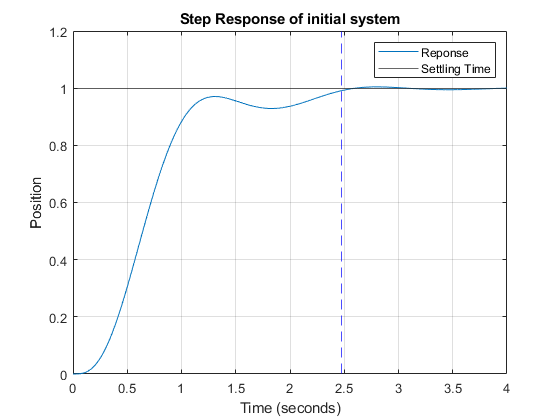

run p2SimInit

position = sim_out1.logsout.get('Position').Values;
stats = stepinfo(position.Data, position.Time, 'SettlingTimeThreshold', 0.01);

figure()
plot(position)
axis([0 4 0 1.2])
yline(1);
xline(stats.SettlingTime, 'b--');
legend('Reponse', 'Settling Time')
title('Step Response of initial system')
grid

[incentive, pass] = incent_func(sim_out1, dt, sensor_time)

incentive = 147.3397

pass = logical
   1


Some revisions of this controller did not meet the settling time requirment, but this ones does. It is m uch harder to get that requirment met by a PI controller comapred to the PID controller tested below. 

### PID Controller

Next a PID controller was used. Again the controller was designed in MATLAB's `controlSystemDesigner` for ease of seeing the (continuous-time) response. The PID controller was tuned a bit to get a nice response, and then another pole was added as without one it is an improper transfer function. The pole was chosen around `-4.5` but this turned out to not have an aggressive enough response, and so the PID gains and the pole were moved around some more. After poking at the gains and moving the poles around on the root locus editor and Bode editor, eventually some nice gains were found. Below is the final controller selected. The simulated 


$$\frac{U\left(s\right)}{E\left(s\right)}=\frac{0\ldotp 03902\left(s^2 +7\ldotp 495s+184\ldotp 5\right)}{s\left(s+6\ldotp 318\right)}$$


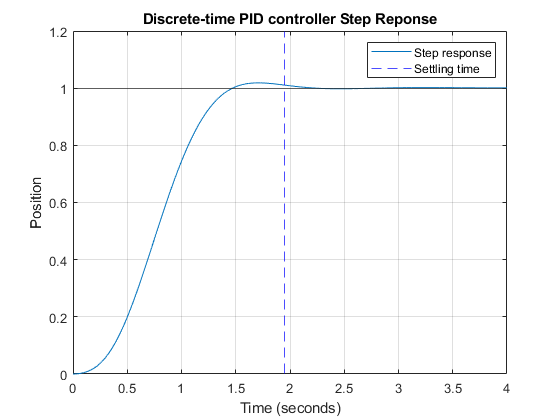

position = sim_out2.logsout.get('Position').Values;
stats = stepinfo(position.Data, position.Time, 'SettlingTimeThreshold', 0.01);

figure()
plot(position)
axis([0, 4, 0, 1.2])
xline(stats.SettlingTime, 'b--');
yline(1);
legend('Step response', 'Settling time')
title('Discrete-time PID controller Step Reponse')
grid


[incentive, pass] = incent_func(sim_out2, dt, sensor_time)

incentive = 143.7223

pass = logical
   1


Surprisingly, the incentive went down with this iteration even though the controller is "more complex". 

## Incentive Tuning

Next the controller and parameters were tuned to squeeze as much incentivized money out of it. This meant going to the controller designer and moving the poles and zeros around to get the best reponse possible, then tuning the CPU and sensor times to get as high as possible. Two findings were observed:

- Lowest sensor time is usually the best.

- Lowest CPU time isn't always the best.

The first one makes sense, the second one if interesting. It seems that the controller's lag makes it overcompensate, leading to faster and smoother response times sometimes when the CPU sampling period is increased.

The process I went about this was the following:

- Adjust the poles of the controller to get the a low settling time

- Adjust the sensor up from 0.04 s to see if the incentive increases. If it does move up until the peak.

- Do a manual gradient ascent to see which CPU sampling time has the highest incentive.

After following the above procedure several times, the following was found to have the highest incentive:


$$\begin{array}{l}
\tau =0\ldotp 04\;s\\
\textrm{ts}=0\ldotp 077\;s\\
\frac{U\left(s\right)}{E\left(s\right)}=\frac{0\ldotp 43875\left(s^2 +3\ldotp 55s+22\ldotp 77\right)}{s\left(s+7\ldotp 363\right)}
\end{array}$$


[incentive, pass] = incent_func(sim_out2_tuned, dt, sensor_time2)

incentive = 154.2330

pass = logical
   1


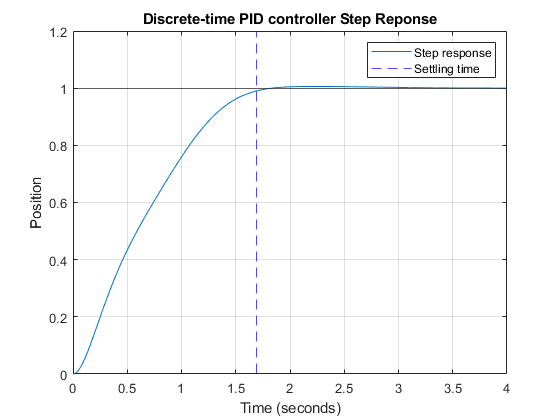

position = sim_out2_tuned.logsout.get('Position').Values;
stats = stepinfo(position.Data, position.Time, 'SettlingTimeThreshold', 0.01);

figure()
plot(position)
axis([0, 4, 0, 1.2])
xline(stats.SettlingTime, 'b--');
yline(1);
legend('Step response', 'Settling time')
title('Discrete-time PID controller Step Reponse')
grid

A thought is to write a non-linear optimizer that adjusts the adjsutable poles and zeros, changes the CPU time, and changes the sensor time to reach the maximum incentive. MATLAB's `controlSystemDesigner` has some sort of optimizer built-in, but I tried it out and it didn't work very well. I let it run for 50 iterations and it never converged on a stable solution, while I was able to get a semi-decent working controller in 10 seconds by hand. Maybe someone who is more experience with optimization, as I am not.

The overall, discrete time, controller in the end is the following:

$\frac{U\left(z\right)}{E\left(z\right)}=\frac{0\ldotp 43875\left(z^2 -1\ldotp 735z+0\ldotp 8377\right)}{\left(z-1\right)\left(z-0\ldotp 5673\right)}$, sampling time = 0.077 seconds

## Summary

Overall this was a very interesting project. I like the free-form design, even though I also found it frustrating as I felt like I had no idea what I was doing often. One example is when I was picking the new pole location of the PID controller. I stuck it inbetween the zeros and called it good enough. Another example is with state-feedback. I attempted to do this, but it was too frustrating too me to do as it kept not working even though I think I was doing it correctly. I need to study state-feedback more as it is very unintuitive to me compared to PID control.

With the tuning, the theoretical  best parameters are interestingly  not always the best. Maybe if the controller was tuned exactly correctly, then possible the "best" sensor and CPU times would lead to the best outcome. But at least I am not able to replicate that. 

rmpath data documents Models scripts